## Controls Systems Textbook Example 10.8

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $P.M.=45\degree,\ K_v\ge20$


$$L(s)=G_C(s)G(s)=\frac{K}{s(s+2)}$$


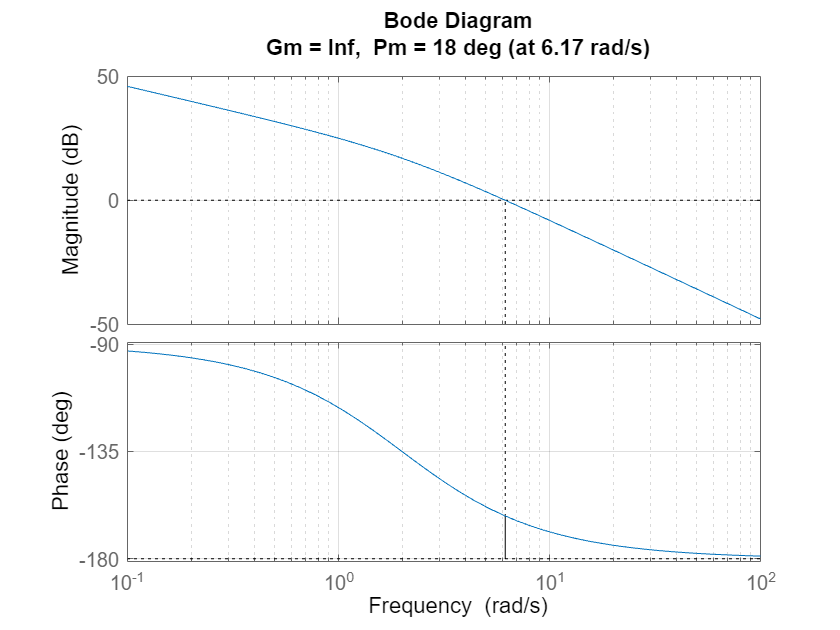

G = 1 / (s * (s + 2));   % type 1
K = 40;
margin(K * G), grid

### Design of a phase-lag compensator


$$20\log_{10}\alpha=20\text{ dB }\Rightarrow\alpha=10$$


**As a general rule of thumb is to place the zero 50 times closer to the origin as the dominant pole.**

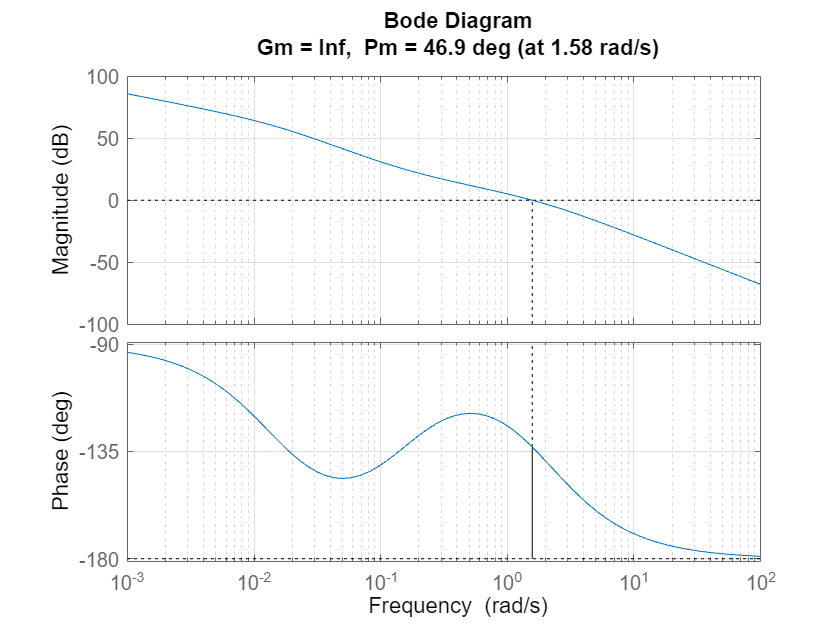

z = 2 / 50;
p = z / 10;
G_C = (p / z) * (s + z) / (s + p);
L = K * G_C * G;
margin(L), grid

K_V = evalfr(s * L, 10^-10)

K_V = 20.0000